Here we consider a complex dynamical system and perform SSM reduction for such a model. SSMTool supports both multiindex notation and tensor notation for the computation of SSM. The multiindex notation assumes real dynamical systsem. The tensor notation, however, does not have such an assumption. Here we test the effectiveness of SSM reduction for complex dynamical systems using tensor-notation-based SSM computation.

We consider a real dynamical system in the following form

$\dot{x}=Ax+F(x)$    (1)

where $x\in\mathbb{R}^n$, $A\in\mathbb{R}^{n\times n}$ and $F:\mathbb{R}^n\to\mathbb{R}^n$. Let $V\in\mathbb{C}^{n\times n}$ be the eigen-matrix of the linear part of the system such that $AV=V\Lambda$, where $\Lambda$ is a diagonal matrix whose diagonal entries are the eigenvalues if $A$ is semi-simple.

Equivalently, we consider a tranformation $x=Vq$ and then obtain a complex dynamical system in the following form

$V\dot{q}=AV q+F(Vq)$     (2).

In the setup of SSMTool, we have $\hat{B}=V\in\mathbb{C}^{n\times n}$, $\hat{A}=AV\in\mathbb{C}^{n\times n}$, and $\hat{F}(q):\mathbb{C}^n\mapsto\mathbb{C}^n$.

In the setting of SSMTool 1.0, the system setup is given as follows

$\dot{q}=\Lambda q+V^{-1}F(Vq)$   (3).

Here we will calculate SSM for (1-3) using SSMTool 2.0 and SSM for (3) using SSMTool 1.0. Then we will compare the computational results.

We consider the modified Shaw-Pierre example studied in [1,2]

$\ddot{x}_1+c(2\dot{x}_1-\dot{x}_2)+k(2x_1-x_2)+\kappa x_1^3=0$,

$\ddot{x}_2+c(2\dot{x}_2-\dot{x}_1)+k(2x_2-x_1)=0$.

We rewrite the above system in first-order form with 


$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\dot{\;x_1 } \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
-2k & k & -2c & c\\
k & -2k & c & -2c
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\dot{\;x_1 } \\
{\dot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-\kappa x_1^3 \\
0
\end{array}\right\rbrack$$


It follows that we obtain $V$ from $[V,\Lambda]=\mathrm{eig}(A)$ and 


$$\hat{F} \left(q\right)=\left\lbrack \begin{array}{c}
0\\
0\\
-{\kappa \left(V_{11} q_1 +V_{12} q_2 +V_{13} q_3 +V_{14} q_4 \right)}^3 \\
0
\end{array}\right\rbrack$$


In particular, we have $(\sum_{i=1}^4 V_{1i}q_i)^3=\sum_{i,j,k}V_{1i}V_{1j}V_{1k}q_i q_j q_k$.

[1] Ponsioen S., Pedergnana T., and Haller G. Automated computation of autonomous spectral submanifolds for nonlinar modal analysis. Journal of Sound and Vibration. (420) 2018 269-295.

[2] Ponsioen S. and Haller G. SSMTool: a short guide

# Computation in second-order real form

## System setup

clear all
k = 3; c=0.03; kappa = 0.5;
mass = eye(2);
damp = [2*c -c;-c 2*c];
stiff = [2*k -k;-k 2*k];
subs = [1 1 1 1];
vals = kappa;
F3 = sptensor(subs, vals, [2,2,2,2]);
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',{[],F3});
set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i



## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','tensor');
resonant_modes = [1 2]; % choose master spectral subspace
order = 5;
S.choose_E(resonant_modes)

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i

sigma_in = 3


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.13E-03 MB
Computing autonomous whisker at order 3
6 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.23E-02 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.35E-02 MB
Computing autonomous whisker at order 5
20 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.72E-02 MB


## Extraction of backbone curve

set(S.FRCOptions,'outdof',1)
omegaRange = [0.8 1.2]*imag(D(1))

omegaRange =     1.3856    2.0784


(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i

sigma_in = 3
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.13E-03 MB
Computing autonomous whisker at order 3
6 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.23E-0

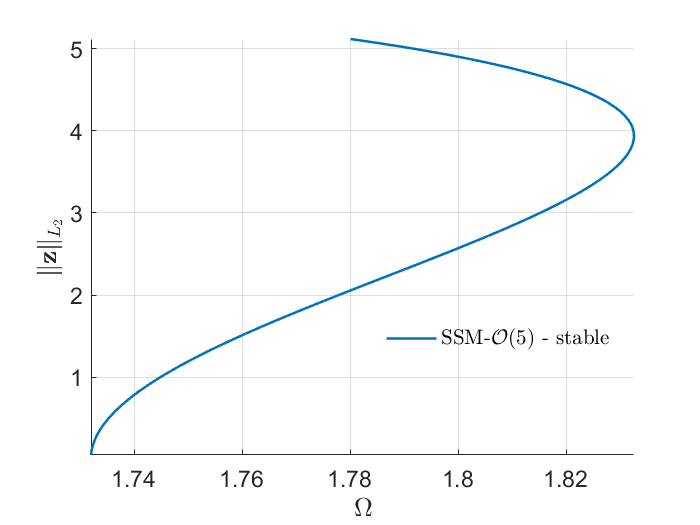

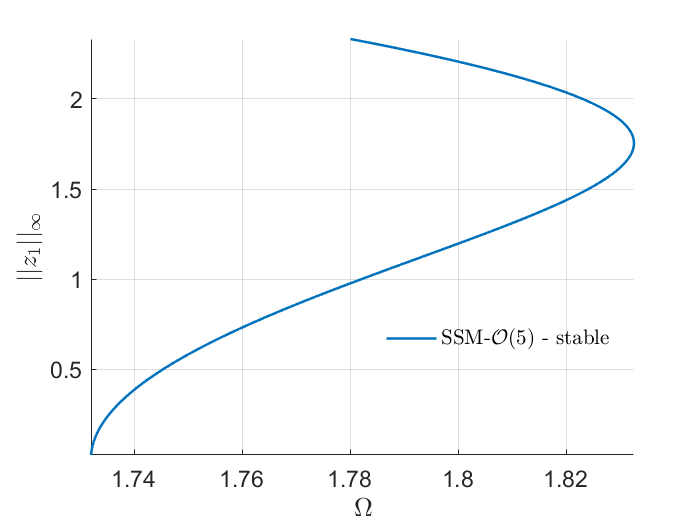

Total time spent on backbone curve computation = 00:00:02


BB = S.extract_backbone(resonant_modes, omegaRange, order);

# Computation in first-order complex form: $\hat{B}=V$, $\hat{A}=AV$

## System setup

clear all
k = 3; c=0.03; kappa = 0.5;
[A,B,F,V] = build_model(c,k,kappa,'non-diagonal');
DS = DynamicalSystem();
set(DS,'A',A,'B',B,'F',F);
set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

### Linear Modal analysis

[V1,D1,W1] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i



% the obtained V1 is not an identity matrix. We overwrite it as an identity
% matrix such that the parameterization coordinates are complex conjugate
% pairs
DS.spectrum.V = eye(4);
DS.spectrum.W = inv(V)';
DS.spectrum.Lambda = D1;

## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','tensor');
resonant_modes = [1 2]; % choose master spectral subspace
order = 5;
S.choose_E(resonant_modes)

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i

sigma_in = 3


% compute autonomous SSM coefficients
[W_0c1,R_0c1] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.01E-02 MB
Computing autonomous whisker at order 3
6 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.53E-02 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.65E-02 MB
Computing autonomous whisker at order 5
20 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.02E-02 MB


## Extraction of backbone curve

gamma = compute_gamma(R_0c1);

gamma = 
  -0.0000 + 0.0271i
  -0.0000 - 0.0018i



nOmega = 100; rhoScale = 1; nRho = 100; lambda = S.E.spectrum(1); nt = 128;
omegaRange = [0.8 1.2]*imag(lambda)

omegaRange =     1.3856    2.0784


% compute backbone
rho = compute_rho_grid(omegaRange,nOmega,rhoScale,gamma,lambda,nRho);
[~,b] = frc_ab(rho, 0, gamma, lambda);
omega = b./rho;
% Backbone curves in Physical Coordinates 
phi = linspace(0,2*pi,nt);
x1 = zeros(numel(rho),1);
for k = 1:numel(rho) % loop over each fixed point
    % periodic response in reduced complex coordinates
    p = [rho(k)*exp(1i*phi); rho(k)*exp(-1i*phi)];
    % periodic response in coordinates q
    q = zeros(4,nt);
    for j = 1:length(W_0c1)
        q = q + expand_multiindex(W_0c1{j},p); % q are complex conjugate pairs
    end
    % periodic response in real coordnates x = Vq
    x = V*q;
    x1(k) = norm(x(1,:),'inf');  
end

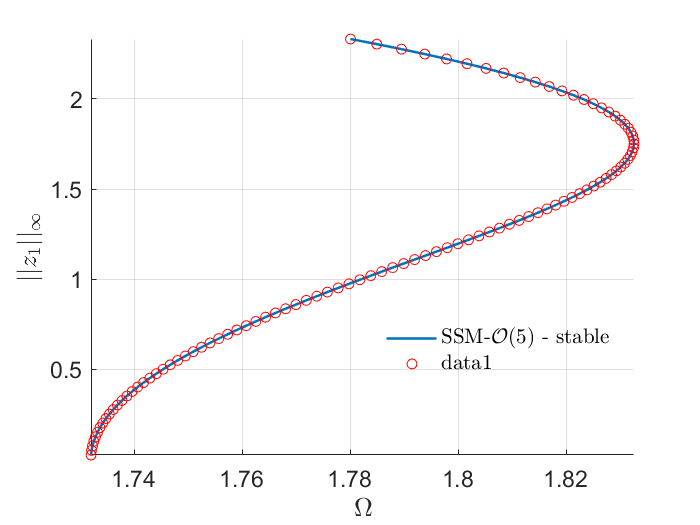

figure(gcf); hold on
plot(omega,x1,'ro');

# Computation in first-order complex form: $\hat{B}=I$, $\hat{A}=\Lambda$

## Diagonal form

clear all
k = 3; c=0.03; kappa = 0.5;
[A,B,F,V] = build_model(c,k,kappa,'diagonal');
DS = DynamicalSystem();
set(DS,'A',A,'B',B,'F',F);
set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

### Linear Modal analysis

[V2,D2,W2] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i



## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','tensor');
resonant_modes = [1 2]; % choose master spectral subspace
order = 5;
S.choose_E(resonant_modes)

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0450 + 2.9997i
  -0.0450 - 2.9997i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i

sigma_in = 3


% compute autonomous SSM coefficients
[W_0c2,R_0c2] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.91E-02 MB
Computing autonomous whisker at order 3
6 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.60E-02 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.55E-02 MB
Computing autonomous whisker at order 5
20 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 5.52E-02 MB


***You may compare the obtained SSM with that of SSMTool 1.0 at the tutorial. They match well.***

gamma = compute_gamma(R_0c2);

gamma = 
  -0.0000 + 0.0271i
  -0.0000 - 0.0018i



nOmega = 100; rhoScale = 1; nRho = 100; lambda = S.E.spectrum(1); nt = 128;
omegaRange = [0.8 1.2]*imag(lambda)

omegaRange =     1.3856    2.0784


% compute backbone
rho = compute_rho_grid(omegaRange,nOmega,rhoScale,gamma,lambda,nRho);
[~,b] = frc_ab(rho, 0, gamma, lambda);
omega12 = b./rho;
% Backbone curves in Physical Coordinates 
phi = linspace(0,2*pi,nt);
x12 = zeros(numel(rho),1);
for k = 1:numel(rho) % loop over each fixed point
    % periodic response in reduced complex coordinates
    p = [rho(k)*exp(1i*phi); rho(k)*exp(-1i*phi)];
    % periodic response in coordinates q
    q = zeros(4,nt);
    for j = 1:length(W_0c2)
        q = q + expand_multiindex(W_0c2{j},p); % z are complex conjugate pairs
    end
    % periodic response in coordnates x = Vq
    x = V*q;
    x12(k) = norm(x(1,:),'inf');  
end

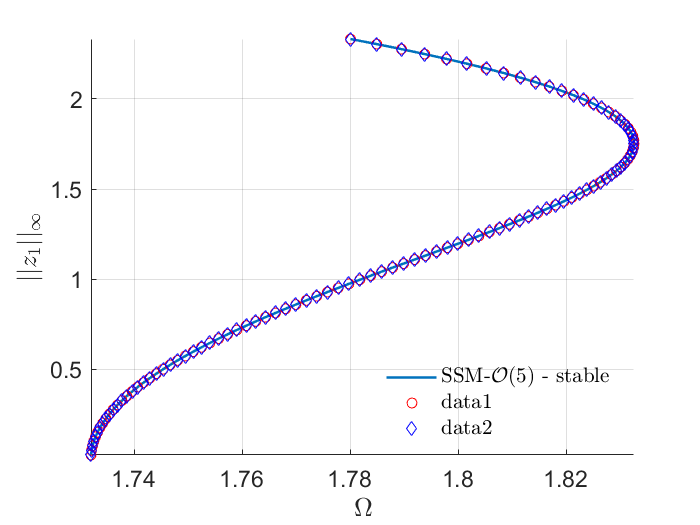

figure(gcf); hold on
plot(omega12,x12,'bd');